# `This solution has been abandoned`

**The weed sample**

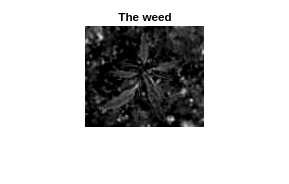

% Let's start by reading the reference image containing
% the object of interest into MATLAB
weed = imread("samples/weed.jpg");
weed = rgb2gray(weed);
weed = imadjust(weed, [0.4 0.8], []);
figure;
imshow(weed);
title('The weed');

**The target image**

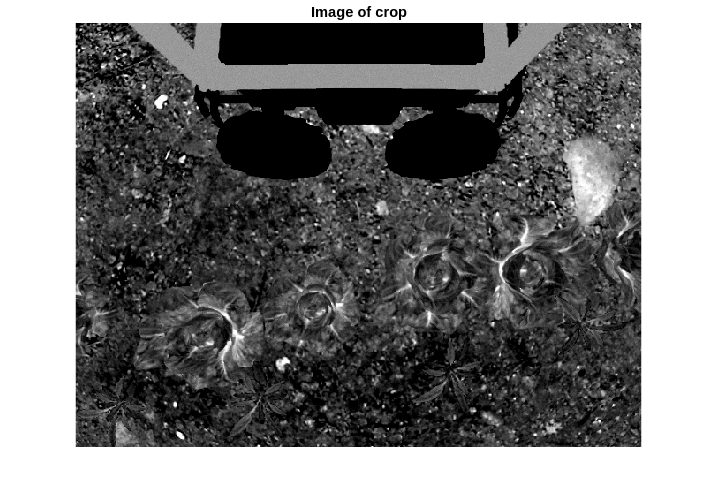

sample = imread('right_sample.png');
sample = rgb2gray(sample);
sample = imadjust(sample, [0.4 0.8], []);
figure;
imshow(sample);
title('Image of crop');

**Detect feature points in both images.**

weed_feature_points = detectSURFFeatures(weed);
sample_feature_points = detectSURFFeatures(sample);

**Then, you can visualize the strongest feature points found in the reference image.**

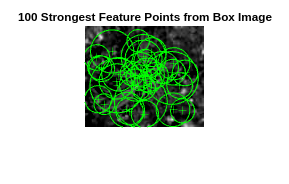

figure;
imshow(weed);
title('100 Strongest Feature Points from Box Image');
hold on;
plot(selectStrongest(weed_feature_points, 100));

**For comparison, visualize the strongest For comparison, visualize the strongest**

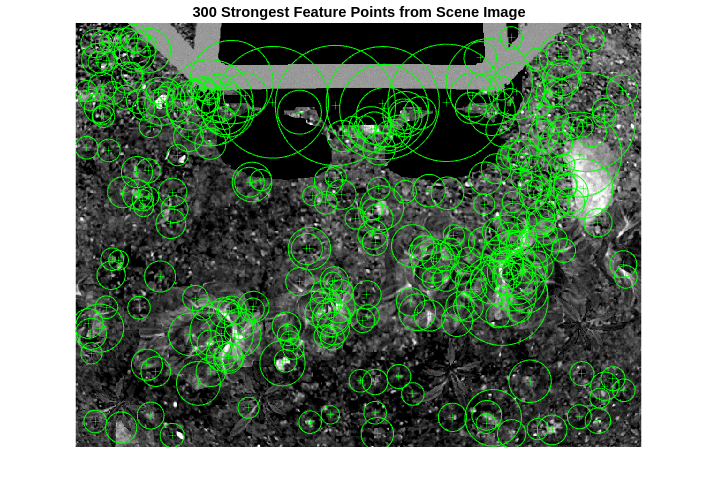

figure;
imshow(sample);
title('300 Strongest Feature Points from Scene Image');
hold on;
plot(selectStrongest(sample_feature_points, 300));

**You can extract feature descriptors at the interest points in both images.**

[weedFeatures, weed_feature_points] = extractFeatures(weed, weed_feature_points);
[sampleFeatures, sample_feature_points] = extractFeatures(sample, sample_feature_points);

%Then match the features using their descriptors.
matchedPoints = matchFeatures(weedFeatures, sampleFeatures);
matchedweed_feature_points = weed_feature_points(matchedPoints(:, 1), :);
matchedsample_feature_points = sample_feature_points(matchedPoints(:, 2), :);

**Show matched features**

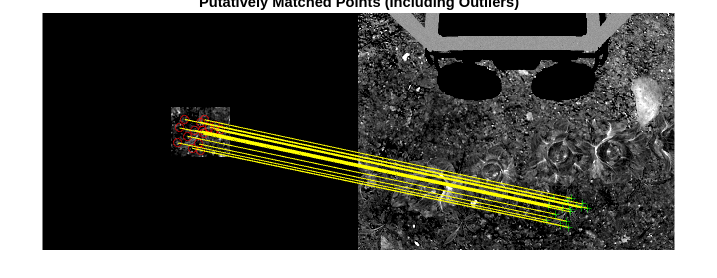

figure;
showMatchedFeatures(weed, sample, matchedweed_feature_points,matchedsample_feature_points, 'montage');
title('Putatively Matched Points (Including Outliers)');

**The estimateGeometricTransform function calculates the transformation relating the matched points,while eliminating outliers.**

**relating the matched points,while eliminating outliers.**

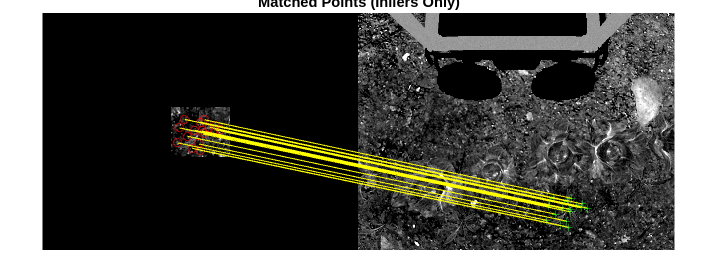

[tform, inlierweed_feature_points, inliersample_feature_points] = ...
 estimateGeometricTransform(matchedweed_feature_points, matchedsample_feature_points,...
 'affine');

% Then show this
figure;
showMatchedFeatures(weed, sample, inlierweed_feature_points, ...
 inliersample_feature_points, 'montage');
title('Matched Points (Inliers Only)');

***Next, get the bounding polygon of the reference image***

Polygon = [1, 1;... % top-left
 size(weed, 2), 1;... % top-right
 size(weed, 2), size(weed, 1);... % bottom-right
 1, size(weed, 1);... % bottom-left
 1, 1]; % top-left again to close the polygon

%To indicate the location of the object in the scene, you can 
% transform the polygon into the coordinate system of the target image.
newPolygon = transformPointsForward(tform, Polygon);

**Then, you can display the detected object**

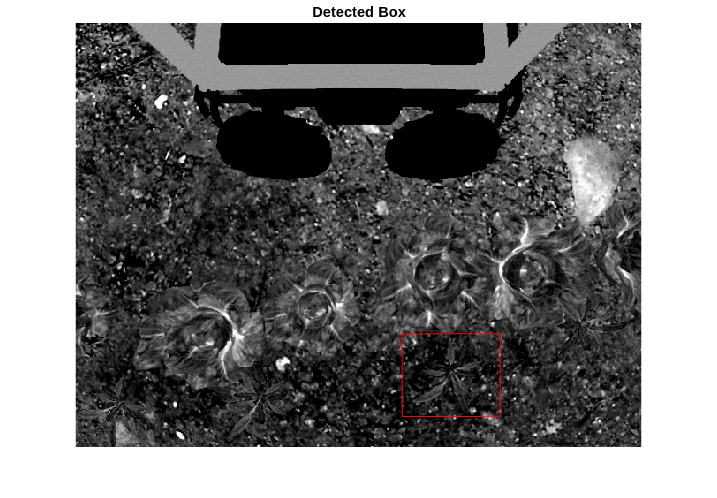

figure;
imshow(sample);
hold on;
line(newPolygon(:, 1), newPolygon(:, 2), 'Color', 'r');
title('Detected Box');

**Localize the weed in the image (u,v)**

centroid = mean(newPolygon);
u = centroid(1)

u = single
414.3582

v = centroid(2)

v = single
389.8106

**Make projection using the camera matrix**